# Linguistic Protoform Summaries (LPSs)

This notebook provides a practical introduction to LPSs. LPSs are template based lingusitic expressions that can be used to summarize numerical data. For example, an LPS summarizing the temprature over a month can be: *Most of the days this month were cold*. Given there linguistic form, they are easier to interpret than there numerical counterparts such as mean, median etc. and are also more descriptive that these standard operators. LPSs use fuzzy sets to model linguistic terms, for example: *most* and *cold* in the above expression.

LPSs are accompanied by Truth-Values which provide their degree of validitiy based on the corresponding data. It varies between 0 and 1. In this notebook, we first describe a method to compute LPSs, called semantic truth value, which was presented in Jain et. al FUZZ-IEEE, 2015. In that paper we proved that this method has properties which make them more intuitive. Please look at the paper for more details. After the LPS computation, a method to compute dissimilarity between two datasets using LPSs is presented (Jain et al, FUZZ-IEEE, 2019). This method provides a numerical as well as linguisatic dissimilarity. The basic problem tackled here is that of given two datasets, how do you compare them based on some property. Traditionally researchers have defiend many metrics to compute dissimilarity between their probability density distributions, all of which give a numerical dissimilarity value. Our method behaves similar to these numerical methods, however, the biggest advantage is that it provides a lingusitic expression of the dissimilarity as well.

Consider a bag containing 1000 balls of different sizes. Fill this bag randomly with the size of balls following the two distributions below 

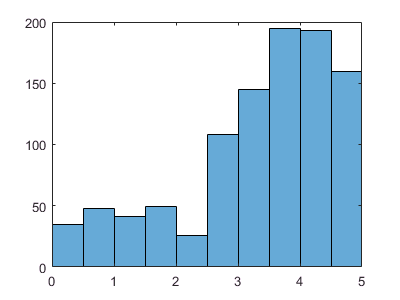

N = 1000;
pdSmall = makedist('Normal','mu',1,'sigma',1);
pdSmall = truncate(pdSmall,0,2.5);
pdBig = makedist('Normal','mu',4,'sigma',1);
pdBig = truncate(pdBig,2.5,5);

bag1.Objects = [my_round(random(pdSmall,1,200)) my_round(random(pdBig,1,N-200))];
h = histogram(bag1.Objects);
h.Parent.Parent.Position = [360 198 400 300];

Now, we wish to summarize the contents of this bag with the help of LPSs. Let's say we want to quantify the amount of Small and Big balls with LPS of the form: *Q balls are Small*, where Q is Quantiifier.The first step is to define the fuzzy sets representing the Summarizer terms: *Small* and *Big* 

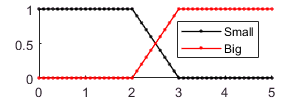

Summarizers.name = {'Small','Big'};
Summarizers.map = containers.Map(Summarizers.name,1:length(Summarizers.name));
Summarizers.set = 0:0.1:5;
Summarizers.parameters(Summarizers.map('Small'),:) = [0 0 2 3];
Summarizers.mf(Summarizers.map('Small'),:) = trapmf(Summarizers.set,...
               Summarizers.parameters(Summarizers.map('Small'),:));
Summarizers.parameters(Summarizers.map('Big'),:) = [2 3 5 5];
Summarizers.mf(Summarizers.map('Big'),:) = trapmf(Summarizers.set,...
               Summarizers.parameters(Summarizers.map('Big'),:));
figure;
plotMembershipFxns(Summarizers);
set(gcf,'Position',[360 198 300 100]);

Now, we define the fuzzy set definations of the Quantifiers, that is the terms: Almost none, few, some, many, small

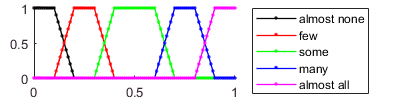

Quantifiers.name = {'almost none','few','some','many','almost all'};
Quantifiers.map = containers.Map(Quantifiers.name,1:length(Quantifiers.name));
Quantifiers.set = 0:0.01:1;
Quantifiers.parameters(Quantifiers.map('almost none'),:) = [0 0 .1 .2];
Quantifiers.mf(Quantifiers.map('almost none'),:) = trapmf(Quantifiers.set,...
               Quantifiers.parameters(Quantifiers.map('almost none'),:));
Quantifiers.parameters(Quantifiers.map('few'),:) = [.1 .2 .3 .4];
Quantifiers.mf(Quantifiers.map('few'),:) = trapmf(Quantifiers.set,...
               Quantifiers.parameters(Quantifiers.map('few'),:));
Quantifiers.parameters(Quantifiers.map('some'),:) = [.3 .4 .6 .7];
Quantifiers.mf(Quantifiers.map('some'),:) = trapmf(Quantifiers.set,...
               Quantifiers.parameters(Quantifiers.map('some'),:));
Quantifiers.parameters(Quantifiers.map('many'),:) = [.6 .7 .8 .9];
Quantifiers.mf(Quantifiers.map('many'),:) = trapmf(Quantifiers.set,...
               Quantifiers.parameters(Quantifiers.map('many'),:));
Quantifiers.parameters(Quantifiers.map('almost all'),:) = [.8 .9 1 1];
Quantifiers.mf(Quantifiers.map('almost all'),:) = trapmf(Quantifiers.set,...
               Quantifiers.parameters(Quantifiers.map('almost all'),:));    
Quantifiers.mf = my_round(Quantifiers.mf);
figure;
plotMembershipFxns(Quantifiers);
set(gcf,'Position',[360 198 400 100]);
set( get(gca,'Legend'),'Orientation','vertical','Location','East Outside')

Compute the membership of each ball in the Summarizer Small and Big. 

bag1.Memberships = getMemberships(bag1.Objects,Summarizers);

Now calcuate the truth-value of each LPSs of the form: Q balls are S, where Q are the 5 quantifier terms and S are the two Summarizer terms. This results in a total of 10 LPSs. We see that the truth-values convey that the majority of balls in the bag are big, while a small number of Small balls. 

bag1.TruthValues = [];
for s = 1:length(Summarizers.name)
    for q = 1:length(Quantifiers.name)
        bag1.TruthValues.(Summarizers.name{s})(q).Quantifier = Quantifiers.name{q};
        bag1.TruthValues.(Summarizers.name{s})(q).tv = ...
            truthValue_proto1_semantic(bag1.Memberships(s,:),...
            Quantifiers.mf(q,:),Quantifiers.set,'relative');
        display([Quantifiers.name{q},' balls are ',Summarizers.name{s}, ...
            ' @ Truth Value = ',num2str(bag1.TruthValues.(Summarizers.name{s})(q).tv)])
    end
end

almost none balls are Small @ Truth Value = 0.2


few balls are Small @ Truth Value = 0.8


some balls are Small @ Truth Value = 0


many balls are Small @ Truth Value = 0


almost all balls are Small @ Truth Value = 0


almost none balls are Big @ Truth Value = 0


few balls are Big @ Truth Value = 0


some balls are Big @ Truth Value = 0


many balls are Big @ Truth Value = 0.8


almost all balls are Big @ Truth Value = 0.2


Now, let's construct another bag with a different distribution in ball sizes. Figure below overlays the distribution of ball sizes for the two bags. We see that the balls in bag 2 are more uniformly distributed. 

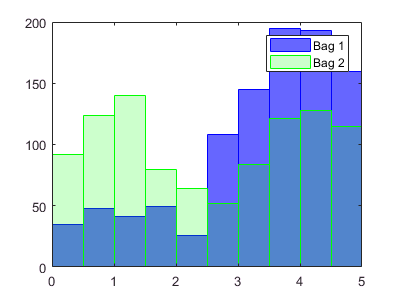

bag2.Objects = [my_round(random(pdSmall,1,500)) my_round(random(pdBig,1,500))];
figure;
histogram(bag1.Objects,'BinEdges',0:0.5:5,'FaceColor','b',...
          'FaceAlpha',0.6,'EdgeColor','b');
hold on;
h = histogram(bag2.Objects,'BinEdges',0:0.5:5,'FaceColor','g',...
                'FaceAlpha',0.2,'EdgeColor','g');
legend({'Bag 1','Bag 2'});
h.Parent.Parent.Position = [360 198 400 300];
hold off;

We compute the LPSs summarizing the amount of Small and Big balls like we did for bag 1. We see that the truth-values convey that bag 2 has some big and some small balls, which is what we observe in the histogram above. 

bag2.Memberships = getMemberships(bag2.Objects,Summarizers);
bag2.TruthValues = [];
for s = 1:length(Summarizers.name)
    for q = 1:length(Quantifiers.name)
        bag2.TruthValues.(Summarizers.name{s})(q).Quantifier = Quantifiers.name{q};
        bag2.TruthValues.(Summarizers.name{s})(q).tv =...
            truthValue_proto1_semantic(bag2.Memberships(s,:),...
            Quantifiers.mf(q,:),Quantifiers.set,'relative');
        display([Quantifiers.name{q},' balls are ',Summarizers.name{s},...
            ' @ Truth Value = ',num2str(bag2.TruthValues.(Summarizers.name{s})(q).tv)])
    end
end

almost none balls are Small @ Truth Value = 0


few balls are Small @ Truth Value = 0


some balls are Small @ Truth Value = 1


many balls are Small @ Truth Value = 0


almost all balls are Small @ Truth Value = 0


almost none balls are Big @ Truth Value = 0


few balls are Big @ Truth Value = 0


some balls are Big @ Truth Value = 1


many balls are Big @ Truth Value = 0


almost all balls are Big @ Truth Value = 0


## Dissimilarity between the two bags

Now, the question: How do the contents of the two bags compare against each other.  

We use the method presented in Jain et al., FUZZ-IEEE 2019. The method compares the two LPS sets using a Fuzzy Inference System (FIS) which returns a numercal as well as lingusitic dissimilarity between the two sets. 

Here, we compare the two bags of balls based on the LPS comprised of the Summarizer Small. The function returns the dissimilarity and the lingsuitic term representing that change. The figure below shows the fuzzy output of the FIS, with the margenta line showing the deffuzified value. The fuzzy sets in this figure (shown by dotted line) are the sets representing the consequents in the FIS.

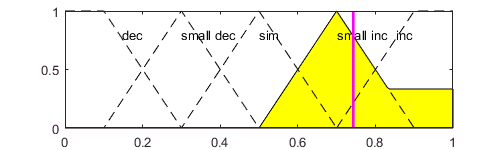

lpsDiffFIS = makeLPSDiffFIS(3);
options.middle = 0.5;
options.viewRules = 1;
[dissim_small,change_small] = lpsFuzzyRuleDissim(bag1.TruthValues.Small,...
                               bag2.TruthValues.Small,lpsDiffFIS,options);

display(['Numerical Dissimilarity = ',num2str(dissim_small),...
    ' | Linguistic Dissimilarity = ',change_small]);

Numerical Dissimilarity = 0.62 | Linguistic Dissimilarity = inc


set(gcf,'Position',[360 198 500 150]);

While the above example shows the change in the two bags for the Summarizer Small, here, we compare the two bags based on both the Summarizers: Small & Big. The overall comparison can be summarized in a lingusitic expression as shown below.

options.viewRules = 0;

for s = 1:length(Summarizers.name) 
    [dissim(s),change{s},deFuzzOut(s),rulesFired{s}] =...
        lpsFuzzyRuleDissim(bag1.TruthValues.(Summarizers.name{s}),...
        bag2.TruthValues.(Summarizers.name{s}),lpsDiffFIS,options);
end
fprintf(['The dissimilarity between bag 1 and bag 2 is ',num2str(mean(dissim)),...
         '.\nThere is a ',change{1},' in the number of ', Summarizers.name{1},' balls and a ',...
         change{2}, ' in the number of ',Summarizers.name{2},' balls.']);

The dissimilarity between bag 1 and bag 2 is 0.62.
There is a inc in the number of Small balls and a dec in the number of Big balls.